
fs=1000

fs = 1000

T=1/fs

T = 1.0000e-03

L=1500

L = 1500

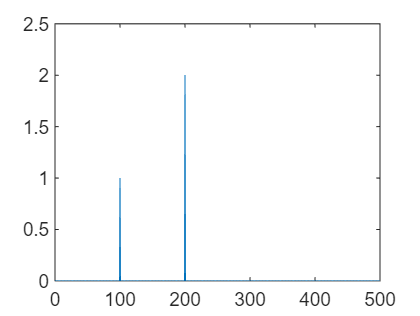

t = (0:L-1)*T; 
X=2*sin(2*pi*200*t);
Y = fft(X);
X1=sin(2*pi*100*t);
Y1=fft(X1);
%X=X+X1;
%Y=fft(X);
%P2 = abs(Y/L);
P2=abs(Y/L)+abs(Y1/L);


P1 = P2(1:L/2+1);
P1(2:end-1) = 2*P1(2:end-1);
f = fs*(0:(L/2))/L;
%disp(f);
plot(f,P1)